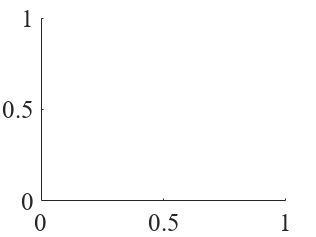

clc
clear all
close all
set(groot, 'DefaultAxesFontName', 'Times New Roman', ...
           'DefaultAxesFontSize', 20, ...
           'DefaultAxesFontWeight', 'normal', ...
           'DefaultTextFontName', 'Times New Roman', ...
           'DefaultTextFontSize', 24, ...
           'DefaultTextInterpreter', 'latex', ...
           'DefaultTextFontWeight', 'normal', ...
           'DefaultLegendInterpreter', 'latex', ...
           'DefaultLegendFontName', 'Times New Roman', ...
           'DefaultLegendFontSize', 20, ...
           'DefaultLegendFontWeight', 'normal', ...
           'DefaultColorbarFontName', 'Times New Roman', ...
           'DefaultColorbarFontSize', 20);

%##########################################################################
load Paderborn_vs_FHN_A10_B1_W15-01-3_RMS.mat

% PNG export
isSave = true; % false for no export
outputFolder = 'D:\some_fhn_stuff\dist_img';

% Each figure in its own window
isNewWin = false; % true to behave like normal .m script
%##########################################################################

T = bearingDataFHN;

%     "K001","K002","K003","K006"           % Healthy
%     "KA01", "KA04","KA05","KA22","KA30"   % IR
%     "KI01", "KI07", "KI16","KI17","KI21"  % OR
%     "N09_M07_F10", "N15_M01_F10", "N15_M07_F04", "N15_M07_F10"


HealthyGroup = 'N09_M07_F10_K003';
IrGroup = 'N09_M07_F10_KA01';
OrGroup = 'N09_M07_F10_KI16';

% Remove all rows with NaN
nanRows = any(ismissing(T), 2);
T(nanRows, :) = [];

% Get all data for healthy
hIdx = contains(T.DataSetEntry, HealthyGroup);
healthy = T(hIdx, :);

% Get all data for IR
irIdx = contains(T.DataSetEntry, IrGroup);
ir = T(irIdx, :);

% Get all data for OR
orIdx = contains(T.DataSetEntry, OrGroup);
or = T(orIdx, :);

w_range = 1500:100:3000;
nBins = 20;

if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

figure
hold on

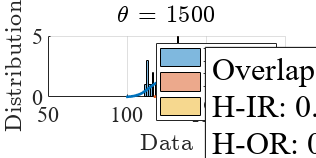

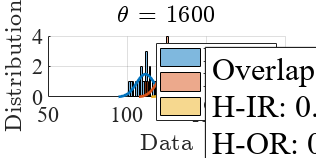

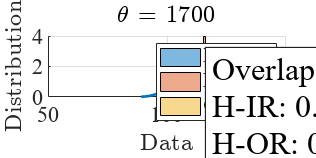

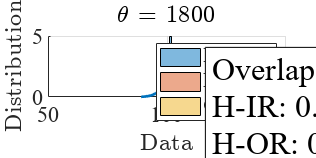

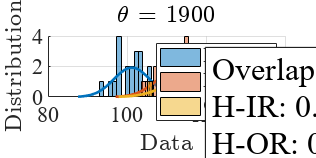

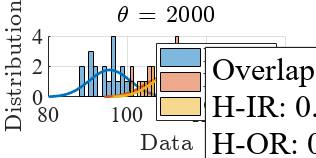

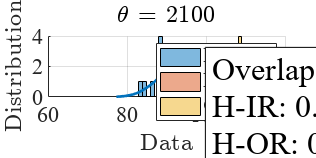

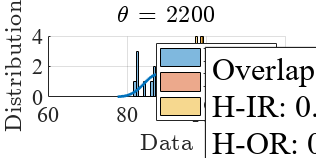

for i = 1:length(w_range)
    datH = healthy(healthy.W == w_range(i),:).("MPD_8e-1");
    datIr = ir(ir.W == w_range(i),:).("MPD_8e-1");
    datOr = or(or.W == w_range(i),:).("MPD_8e-1");
    if (numel(datH) < 15) || (numel(datIr) < 15) || (numel(datOr) < 15)
        continue
    end

    % Calculate the probability density functions
    [fH, xiH] = ksdensity(datH);
    [fIr, xiIr] = ksdensity(datIr);
    [fOr, xiOr] = ksdensity(datOr);

    % Calculate the area of overlap
    overlapHIr = trapz(xiH, min(fH, interp1(xiIr, fIr, xiH, 'linear', 0)));
    overlapHOr = trapz(xiH, min(fH, interp1(xiOr, fOr, xiH, 'linear', 0)));
    overlapIrOr = trapz(xiIr, min(fIr, interp1(xiOr, fOr, xiIr, 'linear', 0)));

    fig = figure;
    hold on
    hh = histfit(datH, nBins); hh(2).Color = [0 0.4470 0.7410]; hh(1).FaceColor = [0 0.4470 0.7410]; hh(1).FaceAlpha = 0.5;
    hir = histfit(datIr, nBins); hir(2).Color = [0.8500 0.3250 0.0980]	; hir(1).FaceColor = [0.8500 0.3250 0.0980]	; hir(1).FaceAlpha = 0.5;
    hor = histfit(datOr, nBins); hor(2).Color = [0.9290 0.6940 0.1250]	; hor(1).FaceColor = [0.9290 0.6940 0.1250]; hor(1).FaceAlpha = 0.5;
    legend("Healthy", "","Ir", "","Or", "")
    xlim([0, 4e3])
    ylabel("Distribution")
    xlabel("Data")
    title(sprintf("$\\theta$ = %d", w_range(i)))
    grid on
    set(gcf, 'Position', [1 100 1280 640]);
    
    % Annotate overlap
    overlapText = sprintf('Overlap estimate\nH-IR: %.2f\nH-OR: %.2f\nIR-OR: %.2f', overlapHIr, overlapHOr, overlapIrOr);
    annotation('textbox', [0.65, 0.5, 0.25, 0.2], 'String', overlapText, 'FitBoxToText', 'on', 'BackgroundColor', 'white');
    
    % Pop out figure window
    if isNewWin
        set(fig,'Visible','on');
    end
    % Save
    if isSave
        saveas(gcf, fullfile(outputFolder, sprintf('Plot_%d.png', w_range(i))));
    end
end